# differential drive mobile robot

## state space

## 3 - define matrixes


A_e = [0 , - pi / 16 ,  0 ; pi/16 , 0 , 3*pi/16 ; 0 , 0 , 0] 

A_e =          0   -0.1963         0
    0.1963         0    0.5890
         0         0         0


B_e = [0.5 , 0.5 ; 0 , 0 ; 1/0.15 , -1/0.15 ] 

B_e =     0.5000    0.5000
         0         0
    6.6667   -6.6667


C_e = [1 , 0 , 0 ;0 , 1 , 0 ; 0 , 0 , 1 ] 

C_e =      1     0     0
     0     1     0
     0     0     1


## 2 - eig

eig(A_e) 

ans =    0.0000 + 0.1963i
   0.0000 - 0.1963i
   0.0000 + 0.0000i


[ T1 , J ] = jordan(A_e) 

T1 =   -3.0000 + 0.0000i   0.0000 - 1.0000i   0.0000 + 1.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


J =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 0.1963i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.1963i


## 3 - transfer function

syms s
G   = (C_e)* inv(( s*eye(3) - A_e )) * B_e 

$$G = \begin{array}{l} \left(\begin{array}{cc} \frac{128\,s}{\sigma_{1}}-\frac{20\,\pi^{2}}{256\,s^{3}+\pi^{2}\,s} & \frac{128\,s}{\sigma_{1}}+\frac{20\,\pi^{2}}{256\,s^{3}+\pi^{2}\,s}\\ \frac{328\,\pi }{\sigma_{1}} & -\frac{312\,\pi }{\sigma_{1}}\\ \frac{20}{3\,s} & -\frac{20}{3\,s} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=256\,s^{2}+\pi^{2} \end{array}$$

%%second order minors
det([G(1) G(4) ; G(2) G(5)])

$$ans = -\frac{320\,\pi }{s\,\left(256\,s^{2}+\pi^{2}\right)}$$

det([G(1) G(3) ; G(4) G(6)])

$$ans = -\frac{5120}{3\,\left(256\,s^{2}+\pi^{2}\right)}$$

det([G(2) G(3) ; G(5) G(6)])

$$ans = -\frac{320\,\pi }{3\,s\,\left(256\,s^{2}+\pi^{2}\right)}$$

G_o = (C_e)* inv(( s*eye(3) - A_e )) ;
G_c = inv(( s*eye(3) - A_e )) * B_e  ;

T = ss(A_e , B_e , C_e , 0)

T =
 
  A = 
            x1       x2       x3
   x1        0  -0.1963        0
   x2   0.1963        0    0.589
   x3        0        0        0
 
  B = 
           u1      u2
   x1     0.5     0.5
   x2       0       0
   x3   6.667  -6.667
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
   y3   0   0
 
Continuous-time state-space model.



## 8 - exp matrix

syms t
phi = expm(A_e*t)

$$phi = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & -\frac{\sigma_{2}\,\mathrm{i}}{2}+\frac{\sigma_{3}\,\mathrm{i}}{2} & \frac{3\,\sigma_{2}}{2}+\frac{3\,\sigma_{3}}{2}-3\\ \frac{\sigma_{2}\,\mathrm{i}}{2}-\frac{\sigma_{3}\,\mathrm{i}}{2} & \sigma_{1} & \frac{3\,\sigma_{2}\,\mathrm{i}}{2}-\frac{3\,\sigma_{3}\,\mathrm{i}}{2}\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{2}}{2}+\frac{\sigma_{3}}{2}\\ \sigma_{2}={\mathrm{e}}^{-\frac{\pi \,t\,\mathrm{i}}{16}}\\ \sigma_{3}={\mathrm{e}}^{\frac{\pi \,t\,\mathrm{i}}{16}} \end{array}$$

% initial condition
x0 = [-0.1;-0.2;-0.2]

x0 =    -0.1000
   -0.2000
   -0.2000


zero_input_ans = C_e * phi * x0 

$$zero\_input\_ans = \begin{array}{l} \left(\begin{array}{c} \frac{3}{5}+\sigma_{1}\,\left(-\frac{7}{20}+\frac{1}{10}\,\mathrm{i}\right)+\sigma_{2}\,\left(-\frac{7}{20}-\frac{1}{10}\,\mathrm{i}\right)\\ \sigma_{1}\,\left(-\frac{1}{10}-\frac{7}{20}\,\mathrm{i}\right)+\sigma_{2}\,\left(-\frac{1}{10}+\frac{7}{20}\,\mathrm{i}\right)\\ -\frac{1}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\pi \,t\,\mathrm{i}}{16}}\\ \sigma_{2}={\mathrm{e}}^{\frac{\pi \,t\,\mathrm{i}}{16}} \end{array}$$

a = zero_input_ans(2)

$$a = {\mathrm{e}}^{-\frac{\pi \,t\,\mathrm{i}}{16}}\,\left(-\frac{1}{10}-\frac{7}{20}\,\mathrm{i}\right)+{\mathrm{e}}^{\frac{\pi \,t\,\mathrm{i}}{16}}\,\left(-\frac{1}{10}+\frac{7}{20}\,\mathrm{i}\right)$$

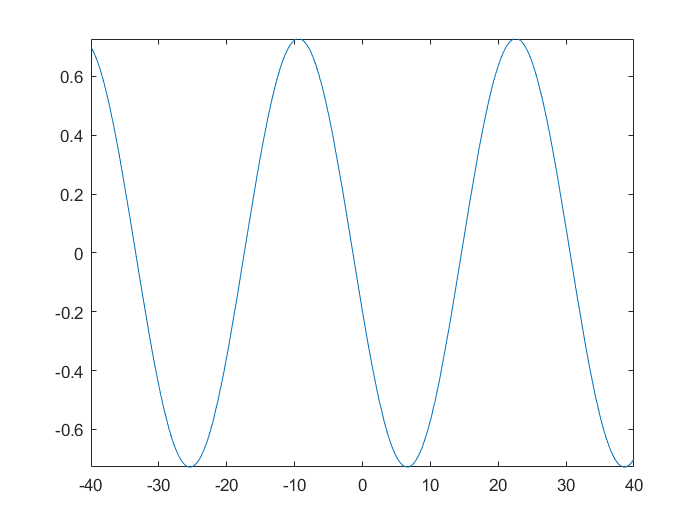

fplot(t,a,[-40,40])

phi_s = laplace(phi);
ilaplace(phi_s)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \sigma_{1} & -\frac{\sigma_{2}\,\mathrm{i}}{2}+\frac{\sigma_{3}\,\mathrm{i}}{2} & \frac{3\,\sigma_{2}}{2}+\frac{3\,\sigma_{3}}{2}-3\\ \frac{\sigma_{2}\,\mathrm{i}}{2}-\frac{\sigma_{3}\,\mathrm{i}}{2} & \sigma_{1} & \frac{3\,\sigma_{2}\,\mathrm{i}}{2}-\frac{3\,\sigma_{3}\,\mathrm{i}}{2}\\ 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\sigma_{2}}{2}+\frac{\sigma_{3}}{2}\\ \sigma_{2}={\mathrm{e}}^{-\frac{\pi \,t\,\mathrm{i}}{16}}\\ \sigma_{3}={\mathrm{e}}^{\frac{\pi \,t\,\mathrm{i}}{16}} \end{array}$$

syms s
U_s = [1/s;1/s]

$$U\_s = \left(\begin{array}{c} \frac{1}{s}\\ \frac{1}{s} \end{array}\right)$$

zero_initial_state_ans = C_e*inv(phi_s)*B_e*U_s

$$zero\_initial\_state\_ans = \left(\begin{array}{c} 1\\ -\frac{\pi }{16\,s}\\ 0 \end{array}\right)$$

zero_initial_state_ans_time = ilaplace(zero_initial_state_ans)

$$zero\_initial\_state\_ans\_time = \left(\begin{array}{c} \delta (t)\\ -\frac{\pi }{16}\\ 0 \end{array}\right)$$

a = zero_initial_state_ans_time(1)

$$a = \delta (t)$$

output_ans = zero_initial_state_ans_time + zero_input_ans

$$output\_ans = \begin{array}{l} \left(\begin{array}{c} \delta (t)+\frac{3}{5}+\sigma_{1}\,\left(-\frac{7}{20}+\frac{1}{10}\,\mathrm{i}\right)+\sigma_{2}\,\left(-\frac{7}{20}-\frac{1}{10}\,\mathrm{i}\right)\\ -\frac{\pi }{16}+\sigma_{1}\,\left(-\frac{1}{10}-\frac{7}{20}\,\mathrm{i}\right)+\sigma_{2}\,\left(-\frac{1}{10}+\frac{7}{20}\,\mathrm{i}\right)\\ -\frac{1}{5} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-\frac{\pi \,t\,\mathrm{i}}{16}}\\ \sigma_{2}={\mathrm{e}}^{\frac{\pi \,t\,\mathrm{i}}{16}} \end{array}$$

## 9- Initial value for specific frequency

% consider initial
% we assume 2nd & 3rd column of T1 which is our similarity transfer matrix
% by this assumtion we dont have our first eigenvalue ( landa_1 = 0)
x1 = [0;2;0]

x1 =      0
     2
     0


C_e * phi * x1

$$ans = \left(\begin{array}{c} -{\mathrm{e}}^{-\frac{\pi \,t\,\mathrm{i}}{16}}\,\mathrm{i}+{\mathrm{e}}^{\frac{\pi \,t\,\mathrm{i}}{16}}\,\mathrm{i}\\ {\mathrm{e}}^{-\frac{\pi \,t\,\mathrm{i}}{16}}+{\mathrm{e}}^{\frac{\pi \,t\,\mathrm{i}}{16}}\\ 0 \end{array}\right)$$

## 10 - Kalman decomposition

Co = ctrb(A_e,B_e)

Co =     0.5000    0.5000         0         0   -0.7903    0.7518
         0         0    4.0252   -3.8288         0         0
    6.6667   -6.6667         0         0         0         0


rank(Co)

ans = 3

Ob = obsv(A_e,C_e)

Ob =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
         0   -0.1963         0
    0.1963         0    0.5890
         0         0         0
   -0.0386         0   -0.1157
         0   -0.0386         0
         0         0         0


rank(Ob)

ans = 3

[Ah,Bh,Ch] = ctrbf(A_e,B_e,C_e)

Ah =          0   -0.1963   -0.5890
    0.1963         0         0
    0.0000         0         0


Bh =          0         0
   -0.5000   -0.5000
   -6.6667    6.6667


Ch =          0   -1.0000   -0.0000
    1.0000         0         0
         0   -0.0000   -1.0000


[Abar,Bbar,Cbar] = obsvf(Ah,Bh,Ch)

Abar =          0   -0.1963   -0.5890
    0.1963         0         0
    0.0000         0         0


Bbar =          0         0
   -0.5000   -0.5000
   -6.6667    6.6667


Cbar =          0   -1.0000   -0.0000
    1.0000         0         0
         0   -0.0000   -1.0000
